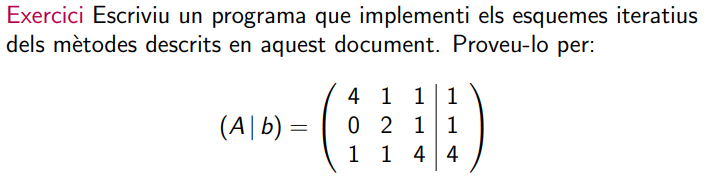

A = E + D + F

J -> B=-D^-1*(E+F) | c D^-1*b

clear
A =  [4 1 1; 0 2 1; 1 1 4];
b = [1 1 4]';

% JACOBI
D= diag(diag(A));       % Diagonal
d= diag(1./diag(A));    % Inversa diagonal
L= tril(A,-1);          % Triangular inferior
U= triu(A,1);           % Triangular superior

Bj= -d*(L + U);
cj= d*b;

% GAUSS
C = inv(L + D);
Bgs = -C * U;
cgs = C * b;

n= 10;
xJ= zeros(size(b));
xG= zeros(size(b));
residus = zeros(n,2);

for i=1:n
    xJ= Bj*xJ + cj; %Jacobi
    xG= Bgs*xG + cgs; % Gauss
    residus(i,1)= norm(b-A*xJ,1);
    residus(i,2)= norm(b-A*xG,1);
end

format short g
table(residus)

ans = 10×1 table
            residus        
    _______________________

         3.25         2.125
         1.75       0.40625
      0.79688      0.091797
      0.42969      0.012604
       0.2041     0.0020218
      0.10547    0.00052023
     0.051697    7.3619e-05
     0.026154    9.8143e-06
     0.012989     2.914e-06
    0.0065193    4.2417e-07


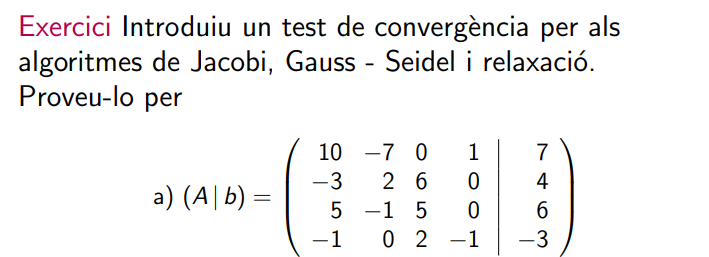

clear;

A= [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1];
b= [7 4 6 -3]';

D= diag(diag(A));       % Diagonal
d= diag(1./diag(A));    % Inversa diagonal
L= tril(A,-1);          % Triangular inferior
U= triu(A,1);           % Triangular superior

w= 1;

% JACOBI REX
Cjr= d;
Bjr= Cjr*((1-w)*D - w*(L+U));
cjr= w*Cjr*b;

% GAUSS REX
Cgr= inv(D+w*L);
Bgr= Cgr*((1-w)*D-w*U);
cgr= w*Cgr*b;

radiJ= max(abs(eig(Bjr)))

radiJ =        1.4584


radiG= max(abs(eig(Bgr)))

radiG =        1.8546


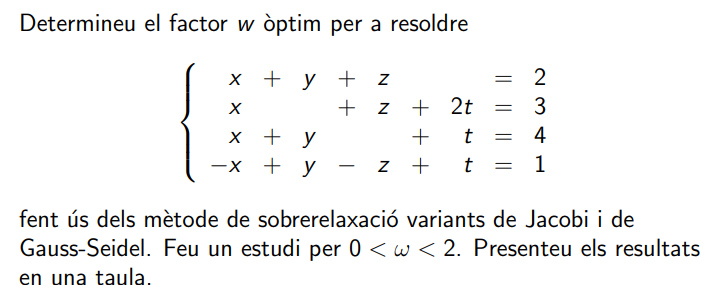

A= [1 1 1 0; -1 1 -1 1; 1 1 0 1;1 0 1 2];
b=[2 3 4 1]';

D= diag(diag(A));       % Diagonal
d= diag(1./diag(A));    % Inversa diagonal
L= tril(A,-1);          % Triangular inferior
U= triu(A,1);           % Triangular superior

% JACOBI REX
Cjr= d;
%Bjr= Cjr*((1-w)*D - w*(L+U));
%cjr= w*Cjr*b;

% GAUSS REX
%Cgr= inv(D+w*L);
%Bgr= Cgr*((1-w)*D-w*U);
%cgr= w*Cgr*b;

w= 0.1:0.1:2;
n=size(w,2);

radiJ=zeros(n,1);
radiG= zeros(n,1);

for i=1:n
    Cgr= inv(D+w(i)*L);
    
    Bjr= Cjr*((1-w(i))*D - w(i)*(L+U));
    Bgr= Cgr*((1-w(i))*D-w(i)*U);
    
    radiJ(i)= max(abs(eig(Bjr)));
    radiG(i)= max(abs(eig(Bgr)));
end

Error using eig
Input matrix contains NaN or Inf.

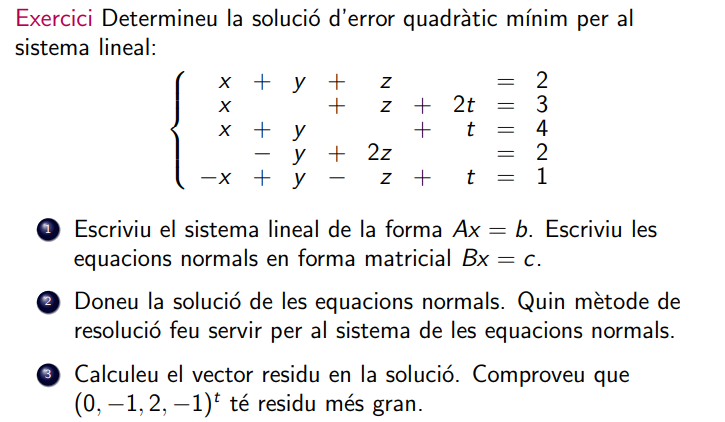

A= [1 1 1 0; 1 0 1 2; 1 1 0 1;0 -1 2 0; -1 1 -1 1];
b=[2 3 4 2 1]';

sol1= A\b
B = A' * A;
c= A'*b;
sol2= B\c
r1= norm(b-A*sol1)
z=[0 -1 2 -1]';
r2= norm(b -A*z)


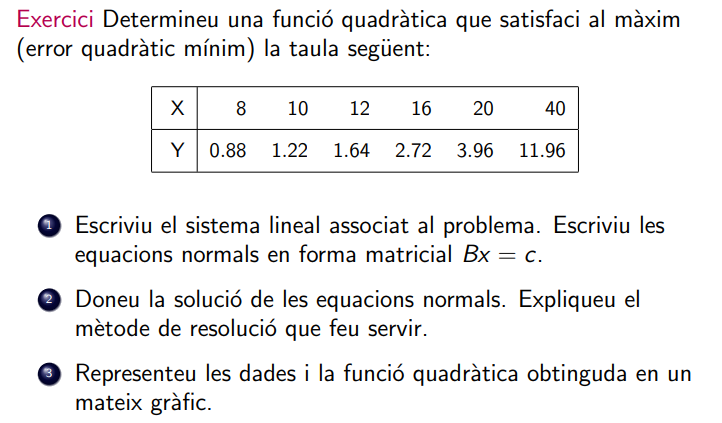

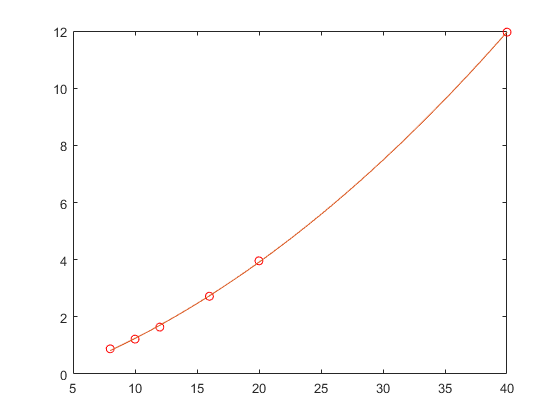

x= [8 10 12 16 20 40];
y= [0.88 1.22 1.64 2.72 3.96 11.96]';
aux= ones(size(x,2),1);

A=[x'.^2,x', aux];
coeffpol= (A'*A)\(A'*y);
r=(polyval(coeffpol,x)-y);

z=8:40;
pz= polyval(coeffpol,z);
plot(x,y,'ro',z,pz)